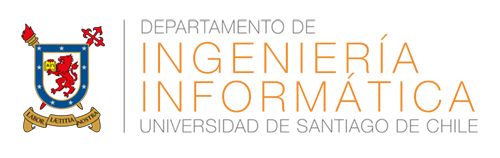

# Laboratorio 4

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# DFT y FFT

La transformada discreta de Fourier (o DFT de "Discrete Fourier Transform") de una secuencia nos permite obtener su contraparte en el dominio de la frecuencia. Actualmente, la implementación más utilizada es la transformada rápida de Fourier (o FFT de Fast Fourier Transform), la cual es un caso especial donde el largo de las secuencias debe ser una potencia de dos. A diferencia de su contraparte continua, la DFT y su implementación en la FFT son siempre simétricas y al ser discretas obtendremos un resultado del mismo largo que la secuencia de entrada.

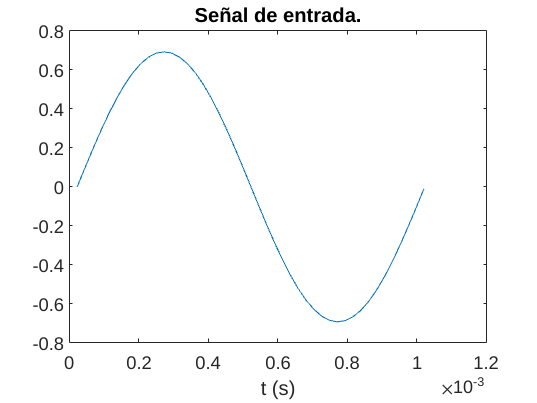

clearvars

[x_n,Fs] = audioread('44100Hz.wav');
x_n = x_n(1:Fs);
x_n = fliplr(x_n);

figure
plot_l = 45;
plot((1:plot_l)./Fs,x_n(1:plot_l))
title('Señal de entrada.')
xlabel('t (s)')

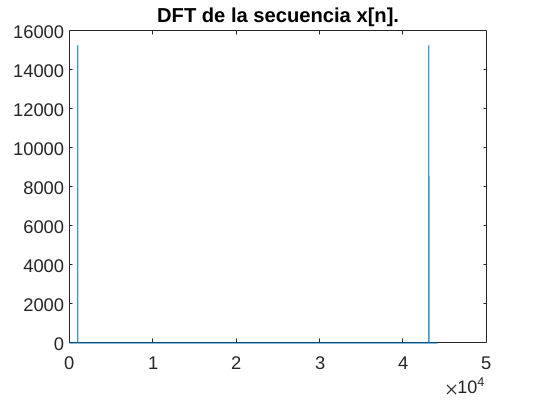


X_ejw = fft(x_n(1:Fs));

figure
plot(abs(X_ejw))
title('DFT de la secuencia x[n].')

Podemos recuperar la secuencia utilizando la transformada inversa de Fourier (siempre que la señal esté libre de aliasing).

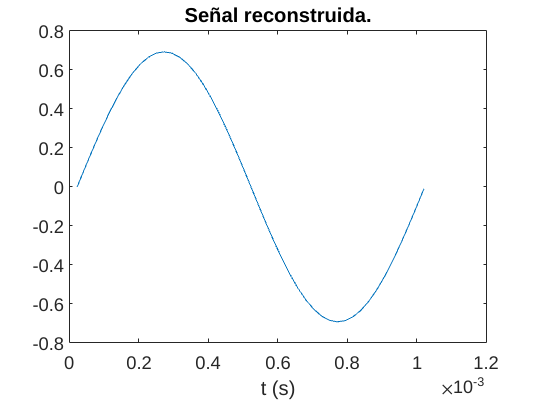

x_n_r = ifft(X_ejw);

figure
plot_l = 45;
plot((1:plot_l)./Fs,x_n_r(1:plot_l))
title('Señal reconstruida.')
xlabel('t (s)')

Al igual que luego de leer una secuencia podíamos obtener los valores para el dominio del tiempo utilizando la frecuencia de muestreo, en este caso utilizamos el mismo valor para obtener el dominio de la frecuencia en Hertz (Hz).

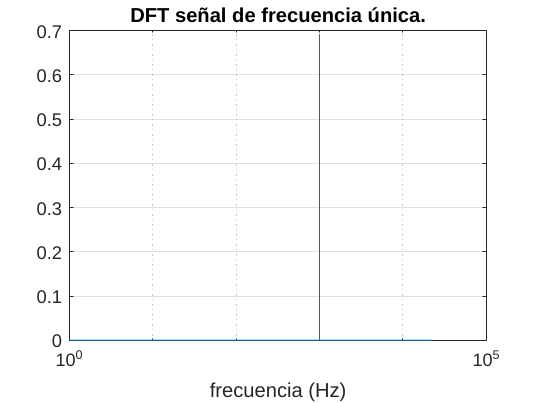

N = length(x_n(1:Fs));
X_ejw = X_ejw(1:round(N/2)+1);
f_hz = Fs*(0:round(N/2))/N;

figure
semilogx(f_hz,2*abs(X_ejw)/N)    % grafico con eje x logaritmico
grid on
title('DFT señal de frecuencia única.')
xlabel('frecuencia (Hz)')

El grafico de magnitud de la transformada de Fourier se conoce como espectro. Nos referimos al ancho de banda como la región del espectro donde se encuentra la mayor energía de la señal, por ejemplo, un ruido blanco tiene igual energía en el espectro completo de frecuencias. 

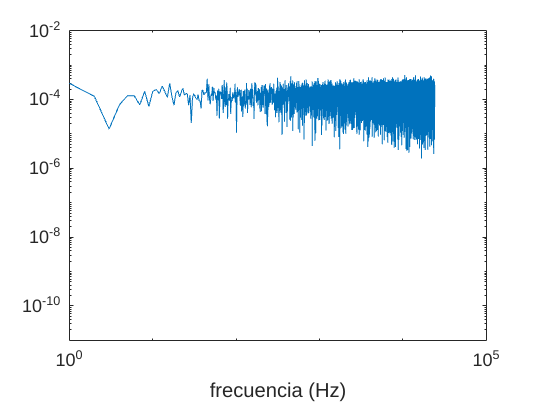

[x_n,Fs] = audioread('white_noise_263s_Matlab10_EDIT.wav');
X_ejw = fft(x_n(1:Fs));
N = length(x_n(1:Fs));
X_ejw = X_ejw(1:round(N/2)+1);
f_hz = Fs*(0:round(N/2))/N;

figure
loglog(f_hz,2*abs(X_ejw)/N)
ylim([10e-12 10e-3])
xlabel('frecuencia (Hz)')

# Transformada Wavelet

La transformada de wavelet se puede aplicar a señales no periódicas o variantes en el tiempo. El análisis a partir de filtros pasa-bajo y pasa-alto en cascada nos permite analizar los niveles y los coeficientes aproximados (cA) y los coeficientes de detalle (cD) de salida.

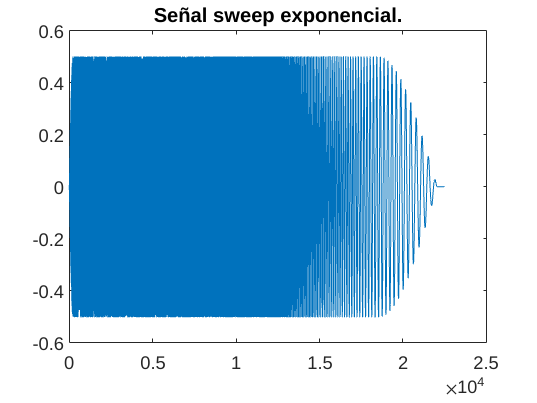

clearvars

Fs = 44100;
y = sweeptone(0.5, 0.01, Fs, 'SweepFrequencyRange',[10000 100]);
% y = fliplr(y);

figure
plot(y)
title('Señal sweep exponencial.')

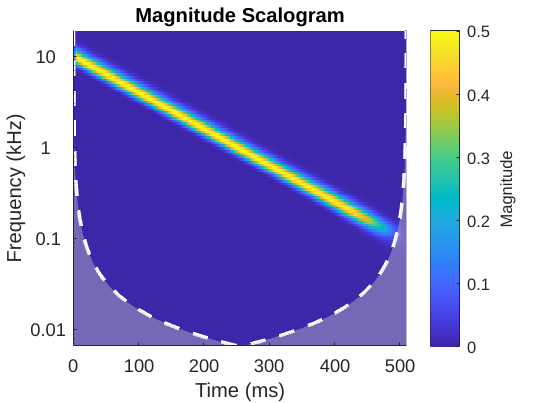


figure
cwt(y,Fs)

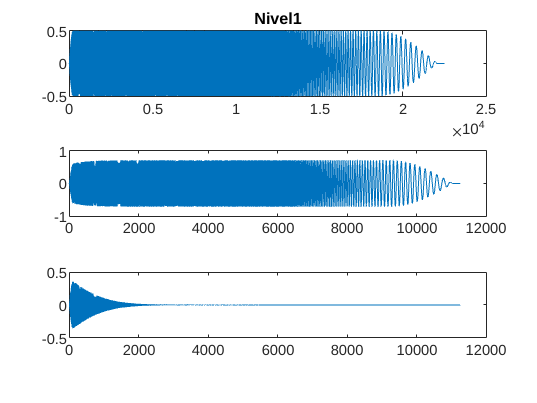

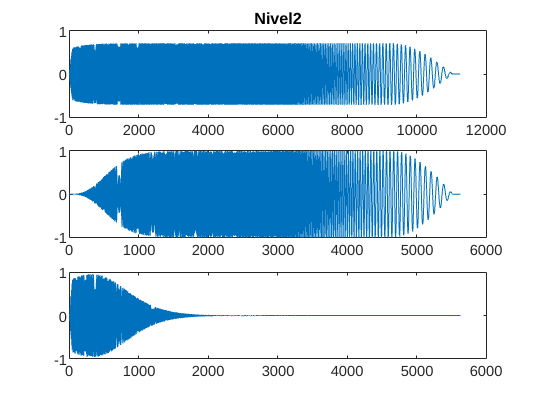

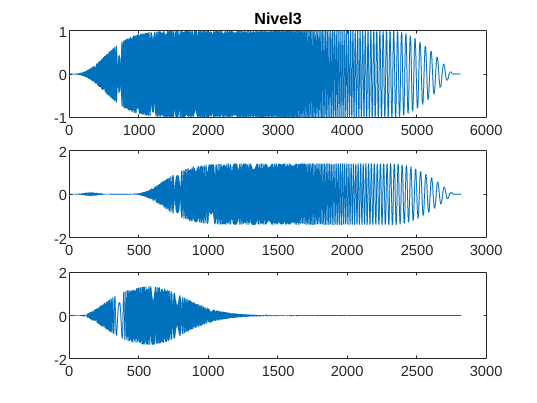

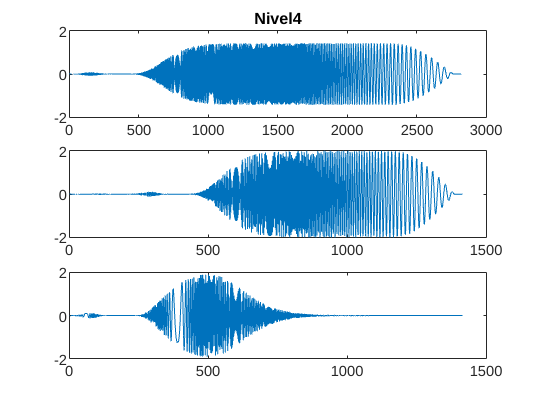

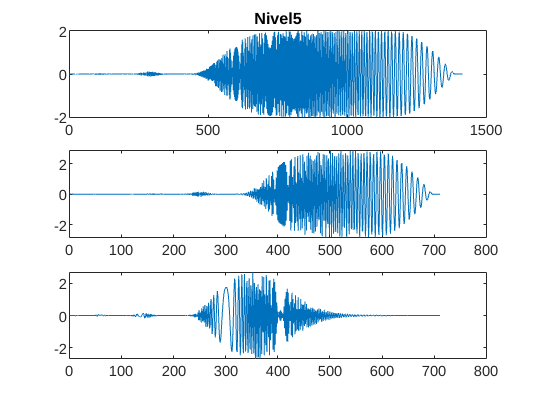


level = 5;
app_coef = cell(1, level);
det_coef = cell(1, level);
idx = 1;
for i = 1:level
    figure
    subplot(3,1,1)
    plot(y)
    title(['Nivel' num2str(i)])
    [y,cD] = dwt(y, 'db5');
    det_coef(1, i) = {cD};
    app_coef(1, i) = {y};
    subplot(3,1,2)
    plot(y)
    subplot(3,1,3)
    plot(cD)
end

Al igual que con la transformada de Fourier, podemos reconstruir la señal con cada par cA-cD generado por nivel hasta reconstruir la señal original.

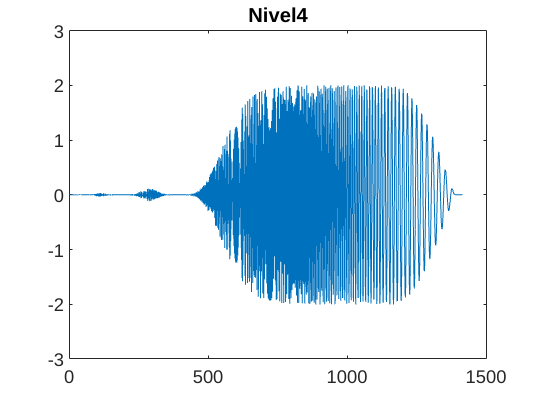

y = idwt(cell2mat(app_coef(1,i)), cell2mat(det_coef(1,i)), 'db5');
figure
plot(y)
title(['Nivel' num2str(level-1)])

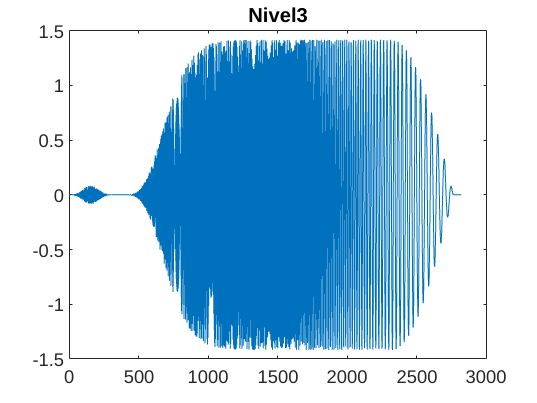

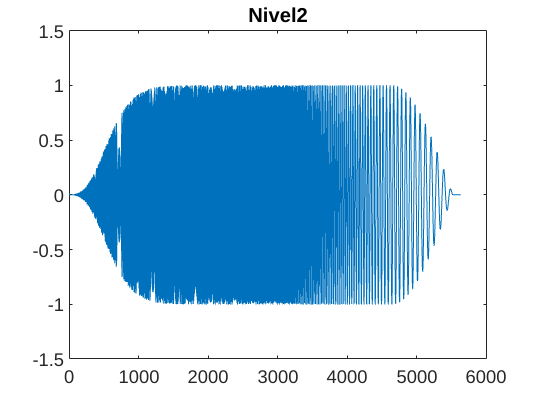

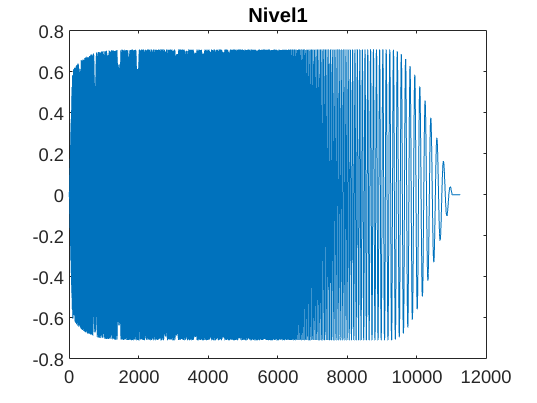

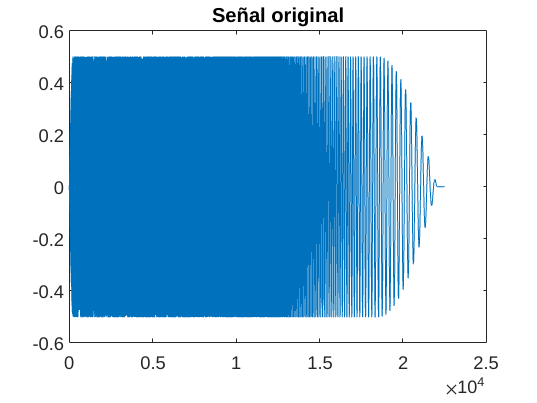

for i = level-1:-1:1
    if length(y) > length(cell2mat(det_coef(1,i)))
        y = y(1:end-1);
    end
    y = idwt(y, cell2mat(det_coef(1,i)), 'db5');
    figure
    plot(y)
    if i-1 == 0
        title('Señal original')
    else
        title(['Nivel' num2str(i-1)])
    end
end

Es posible generar la salida de un nivel especifico con las funciones wavedec. appcoef y detcoef.

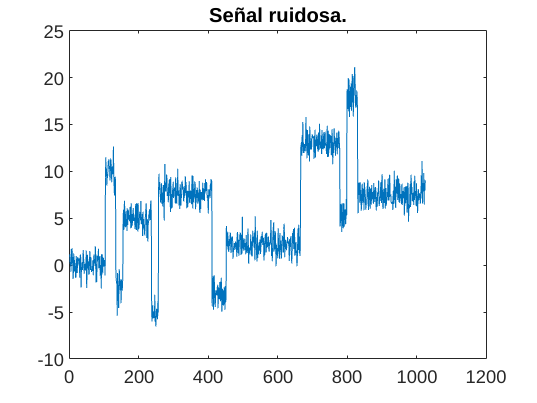

% clearvars

load noisbloc
s = noisbloc;
sLen = length(s);

nivel = 3;
[c,l] = wavedec(s,nivel,'db2');
approx = appcoef(c,l,'db2');
cd3 = detcoef(c,l,nivel);

plot(s)
title('Señal ruidosa.')

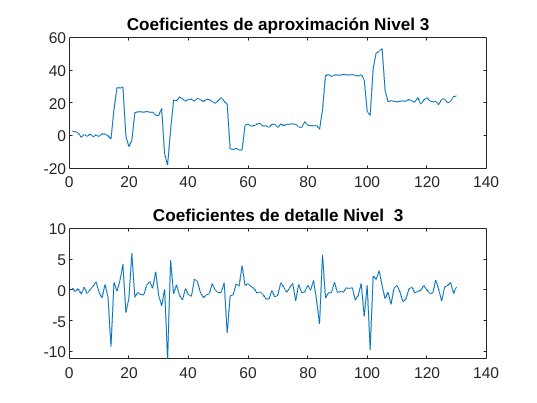


subplot(2,1,1)
plot(approx)
title(['Coeficientes de aproximación Nivel ' num2str(nivel)])
subplot(2,1,2)
plot(cd3)
title(['Coeficientes de detalle Nivel  ' num2str(nivel)])

# Referencias

[1] *Fast Fourier transform - MATLAB fft --- mathworks.com.* [https://mathworks.com/help/releases/R2020a/matlab/ref/fft.html](https://mathworks.com/help/releases/R2020a/matlab/ref/fft.html), [Accessed 23-May-2023]

[2] *Continuous Wavelet Analysis ---  mathworks.com.* [https://la.mathworks.com/help/wavelet/gs/continuous-wavelet-analysis.html](https://la.mathworks.com/help/wavelet/gs/continuous-wavelet-analysis.html), [Accessed 23-May-2023]